# doble_integracion_msi

performs the integral double of a sampled signal with the MSI method.

## Syntax

pos=doble_integracion_msi(acc,freq)

## Description

`pos=doble_integracion_msi(acc,freq)` performs the integral double of a signal `acc` sampled at `freq` Hz. 		

The idea is to remove the non-zero medium value, maybe caused by sensor artifacts and uncertainties, prior to the first velocity integration. The mean value of the acceleration between two consecutive integration events was is subtracted, and a first integration is made to estimate the instantaneous velocity. Notice that forcing the acceleration to have a zero mean value is equivalent to assuming that the velocity is the same at the beginning and the end of the integration time.

				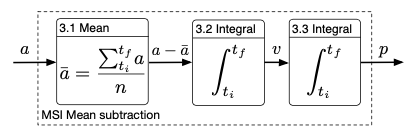

A mean subtraction was applied twice in the particular case where the final position is the same at the beginning and end of the integration period, but this case is not implemented. 

More information: 

Alvarez, J.C.; González, R.C.; Alvarez, D.; López, A.M.; Rodríguez-Uría, J. Multisensor approach to walking distance estimation with foot inertial sensing. *Conf. Proc. IEEE Eng. Med. Biol. Soc. ***2007**, *2007*, 5720–5723. 								 				

## Examples

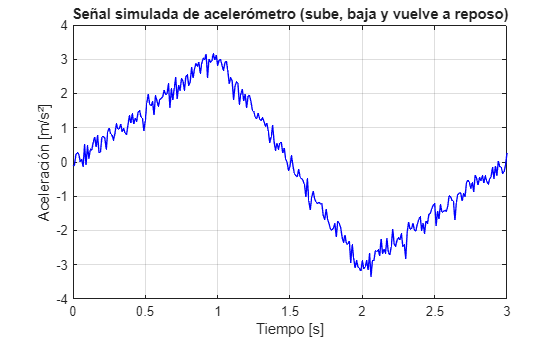

% Simulamos una señal de acelerómetro que sube, baja y vuelve a reposo con ruido
fs = 100;                     % Frecuencia de muestreo [Hz]
t = 0:1/fs:3;                 % Duración de 3 segundos
n = length(t);

% Creamos una forma de aceleración: subida, bajada, reposo
fase1 = linspace(0, 3, round(n/3));       % subida
fase2 = linspace(3, -3, round(n/3));      % bajada
fase3 = linspace(-3, 0, n - 2*round(n/3));% vuelta a reposo
acc_real = [fase1 fase2 fase3];           % concatenamos

% Añadimos ruido gaussiano para simular el sensor
ruido = 0.2*randn(1, n);
acc = acc_real + ruido;

% Visualizamos la señal simulada
figure
plot(t, acc, 'b')
xlabel('Tiempo [s]')
ylabel('Aceleración [m/s²]')
title('Señal simulada de acelerómetro (sube, baja y vuelve a reposo)')
grid on

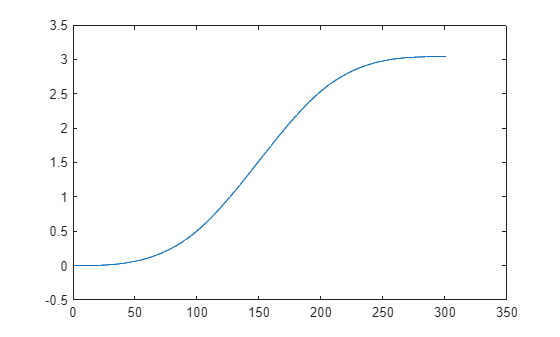


plot(doble_integracion_msi(acc,100));